## Problem 1a

clear

s = tf('s');
G = (-s+3) / ((s+2)*(s+1000)) * exp(-0.005*s);

wh = 1000;
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);

gmd = db2mag(6);
pmd = 40;

while(abs(w_new-w_try)>.001)
    w_try = w_new;

    % Desired loop shape
    Ld = 1/s^2 * (s+0.1*w_try)/(s+10*w_try) * (-s+3)/(s+3) * exp(-0.005*s);

    [mag, phase] = bode(Ld, w_try);
    Ld = Ld/mag;

    % Get GM and PM
    [Gm,Pm,Wcg,Wcp] = margin(Ld);
    if Gm>gmd
        wl = w_try;
    else
        wh = w_try;
    end
    w_new = 1/2*(wh+wl);
end

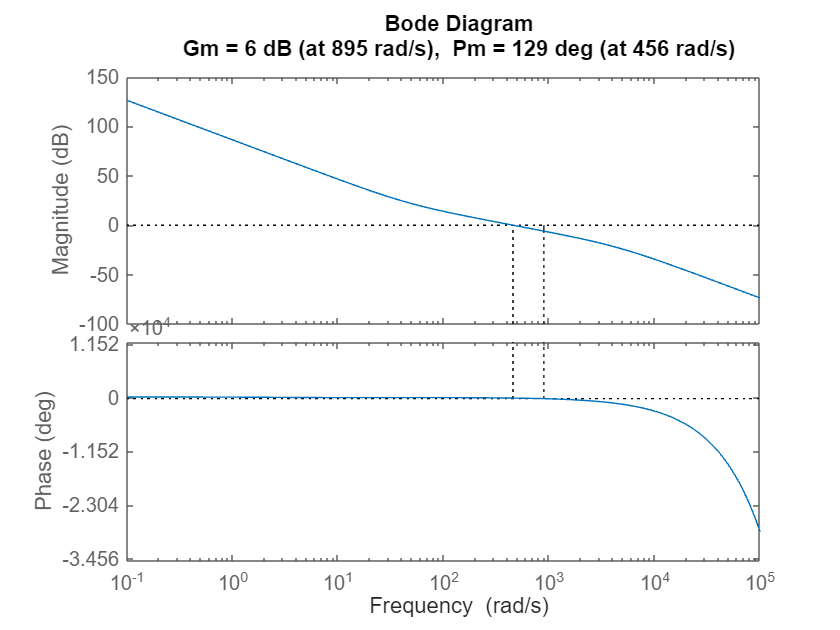

K = ((s+2)*(s+1000) * (s+0.1*w_try))/(s^2*(s+10*w_try)*(s+3));
[mag, phase] = bode(G*K, w_try);
K = K/mag;
margin(G*K)

## Problem 1b

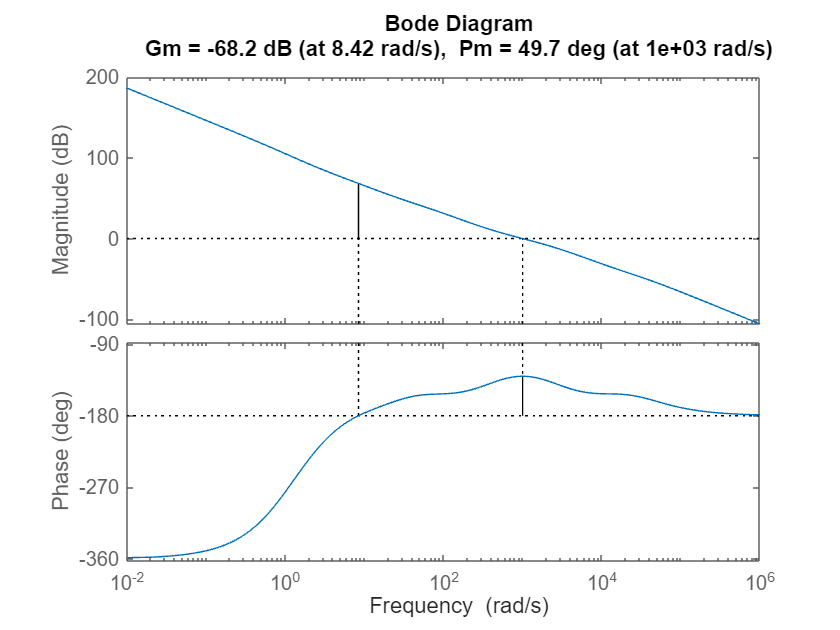

s = tf('s');
G = (s+5)/((-s+1)*(s+1000));
wc = 1000;

[K, CL, GAM] = loopsyn(G, wc^2/s^2);
N = norm(1-CL, 'inf');

margin(G*K)

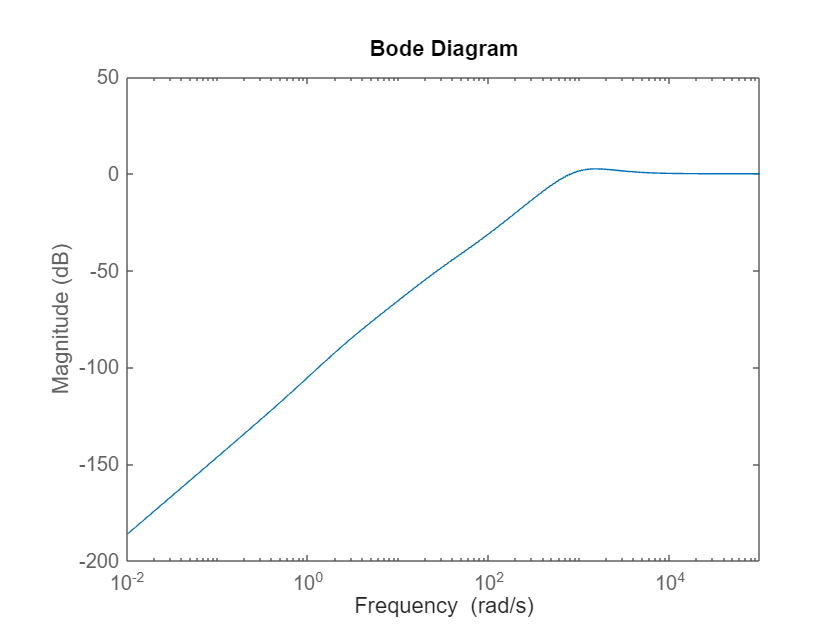

bodemag(1-CL)

## Problem 2a

clear

% Get the plant
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
P = Gv*Gv1*Gv2*Gv3*Gv4;

M = db2mag(6);
A = db2mag(-60);
wc = 3000*2*pi;

% First order weights
Ws = makeweight(1/A, wc, 1/M);
[K, CL, GAM] = mixsyn(P, Ws, [], []);
GAM

GAM = 0.5884

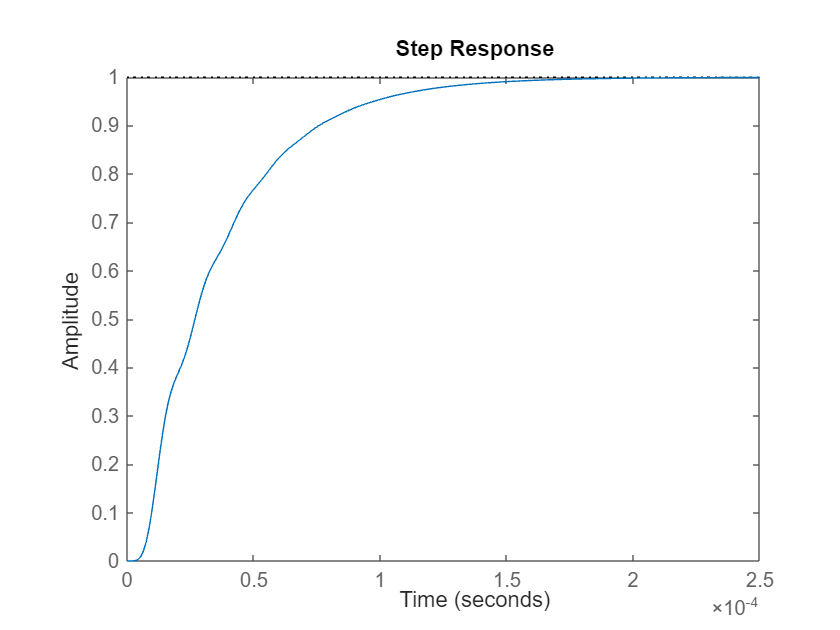

margin(P*K)
bodemag(inv(1+P*K), 1/Ws)
step(feedback(P*K, 1))

% Second order weights
Ws = makeweight(1/A, wc, 1/M, 0, 2);
[K, CL, GAM] = mixsyn(P, Ws, [], []);
GAM

GAM = 0.6006

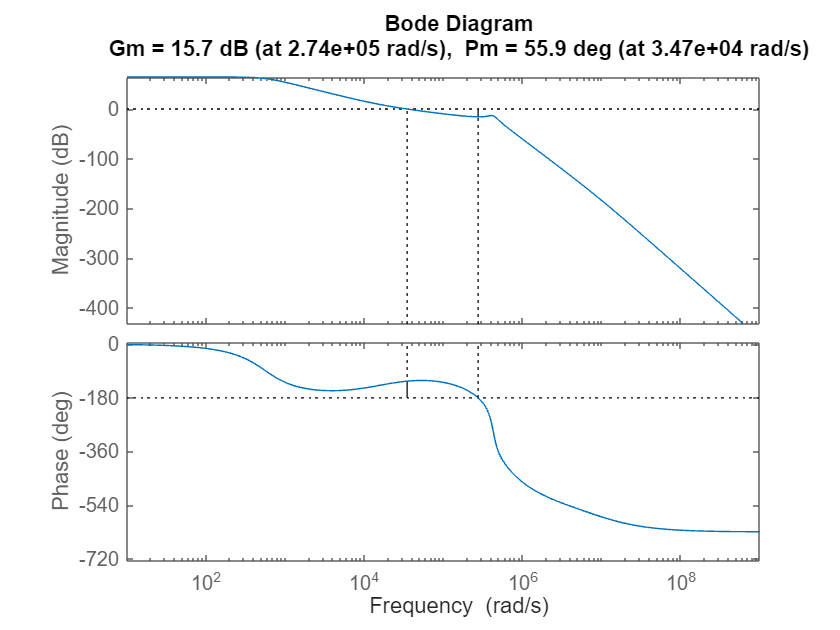

margin(P*K)

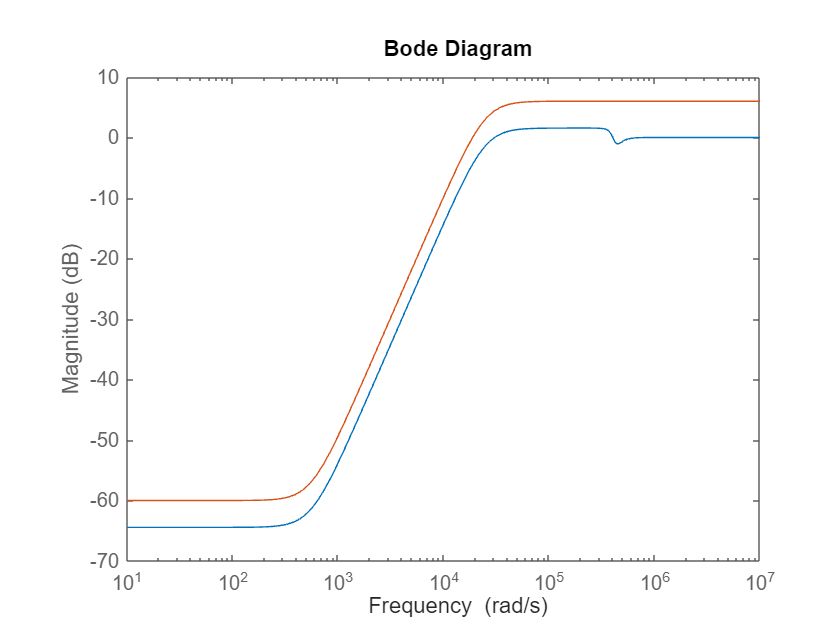

bodemag(inv(1+P*K), 1/Ws)

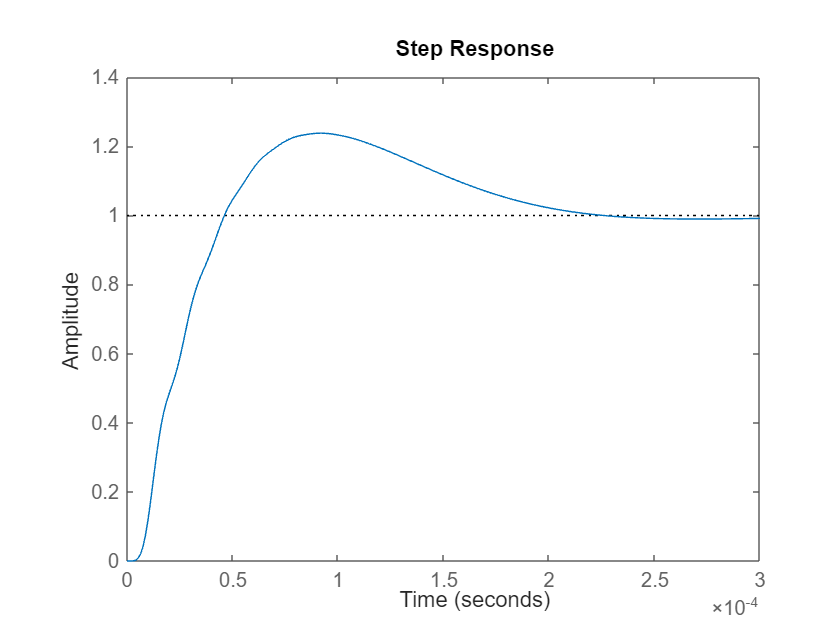

step(feedback(P*K, 1))

## Problem 2b

M = db2mag(6);
A = db2mag(-60);
wc = 3000*2*pi;
Mt = db2mag(10);
At = db2mag(-20);
wct = 10000*2*pi;

Ws = makeweight(1/A, wc, 1/M, 0, 2);
Wt = makeweight(1/Mt, wct, 1/At);
[K, CL, GAM] = mixsyn(P, Ws, [], Wt);
GAM

GAM = 0.8702

margin(P*K)
bodemag(inv(1+P*K), 1/Ws)

bodemag(inv(1+P*K)*P*K, 1/Wt)

## Problem 2c

wc = 800;
GAM = 0;

M = db2mag(6);
A = db2mag(-60);
Mt = db2mag(10);
At = db2mag(-20);
Wu = 1/100;
K = 0;

while GAM < 1
    wc = wc+1;
    K_old = K;
    Ws = makeweight(1/A, wc*2*pi, 1/M, 0, 2);
    Wt = makeweight(1/Mt, 5*wc*2*pi, 1/At);
    [K, CL, GAM] = mixsyn(P, Ws, Wu, Wt);
end

K = K_old;
wc = wc-1;
wc*2*pi

ans = 5.6800e+03

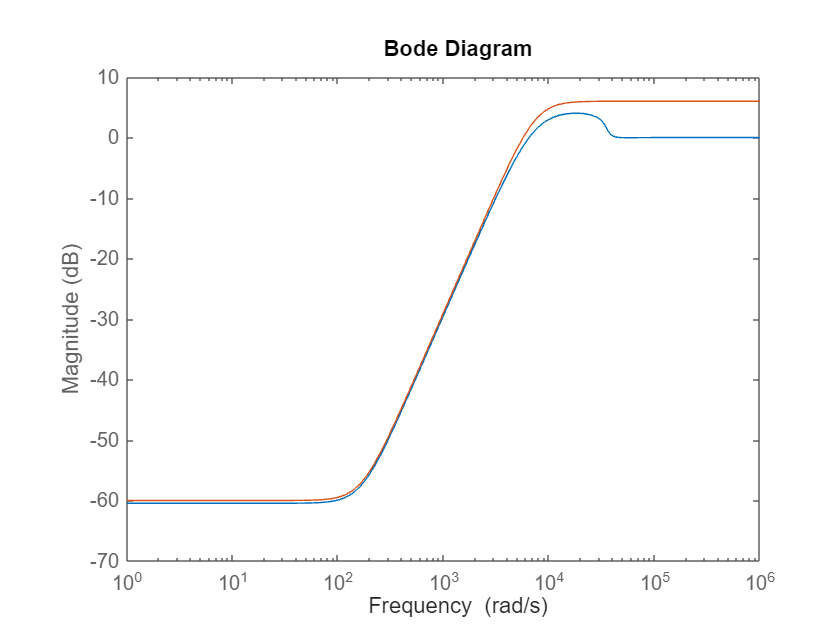

bodemag(inv(1+P*K), 1/Ws)

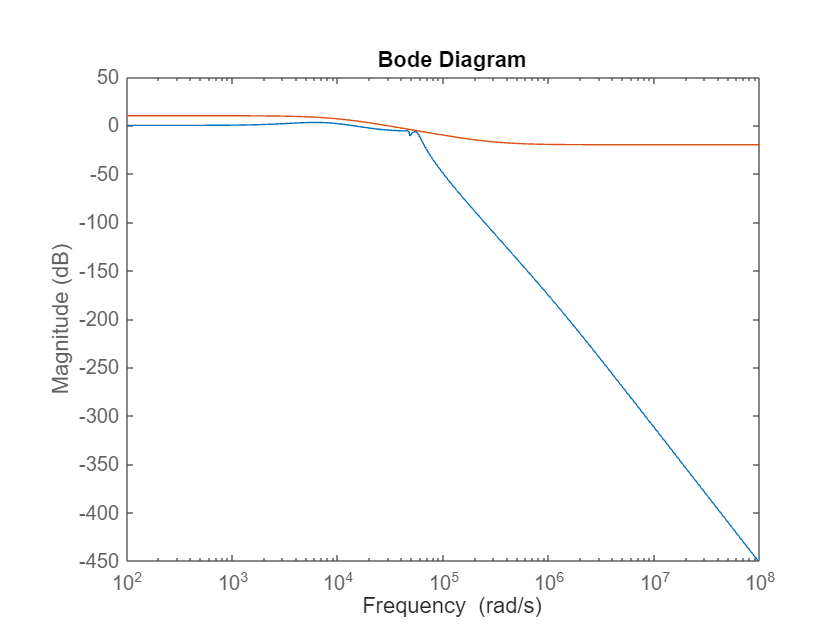

bodemag(inv(1+P*K)*P*K, 1/Wt)

n = norm(CL, 'inf')

n = 1.0001

## Problem 3a

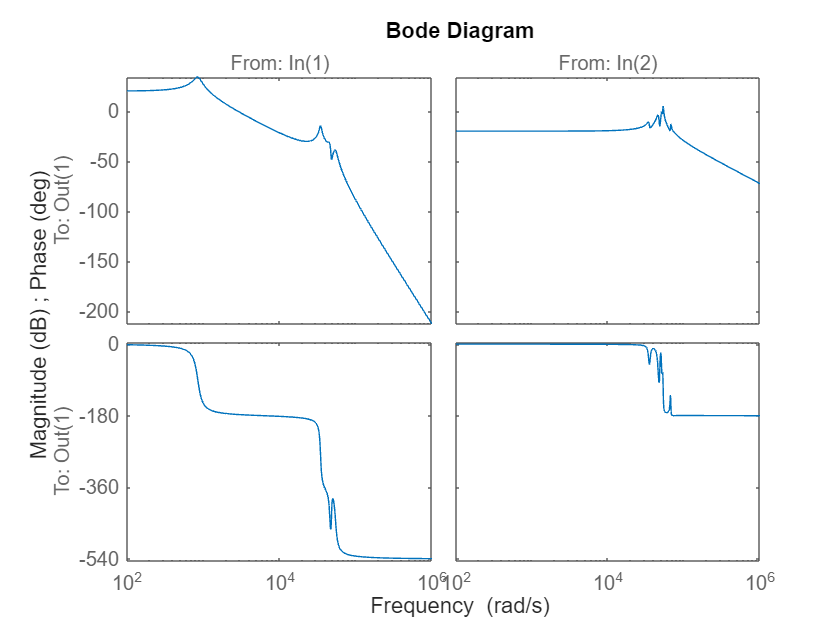

clear

Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4;

Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*8460)^2,[1 2*0.01*2*pi*8460 (2*pi*8460)^2]);
Gp2 = 5500^2/5650^2*tf([1 2*.03*2*pi*5650 (2*pi*5650)^2],[1 2*.03*2*pi*5500 (2*pi*5500)^2]);
Gp3 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
Gp4 = 8070^2/8250^2*tf([1 2*.02*2*pi*8250 (2*pi*8250)^2],[1 2*.015*2*pi*8070 (2*pi*8070)^2]);
Gp5 = 10650^2/10530^2*tf([1 2*.015*2*pi*10530 (2*pi*10530)^2],[1 2*.01*2*pi*10650 (2*pi*10650)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5;

P = [VCM PZT];
bode(P)

## Problem 3b

wc = 2000;
GAM = 0;

M = db2mag(6);
A = db2mag(-60);
Mt = db2mag(10);
At = db2mag(-20);
Wu_vcm = 1/100;
Wu_pzt = 1/10;
K = 0;

while GAM < 1
    wc = wc+1;
    K_old = K;
    Ws = makeweight(1/A, wc*2*pi, 1/M, 0, 2);
    Wt = makeweight(1/Mt, 5*wc*2*pi, 1/At);
    Wu = [Wu_vcm 0 ; 0 Wu_pzt];
    [K, CL, GAM] = mixsyn(P, Ws, Wu, Wt);
end

K = K_old;
wc = wc-1;
wc*2*pi

ans = 1.2830e+04

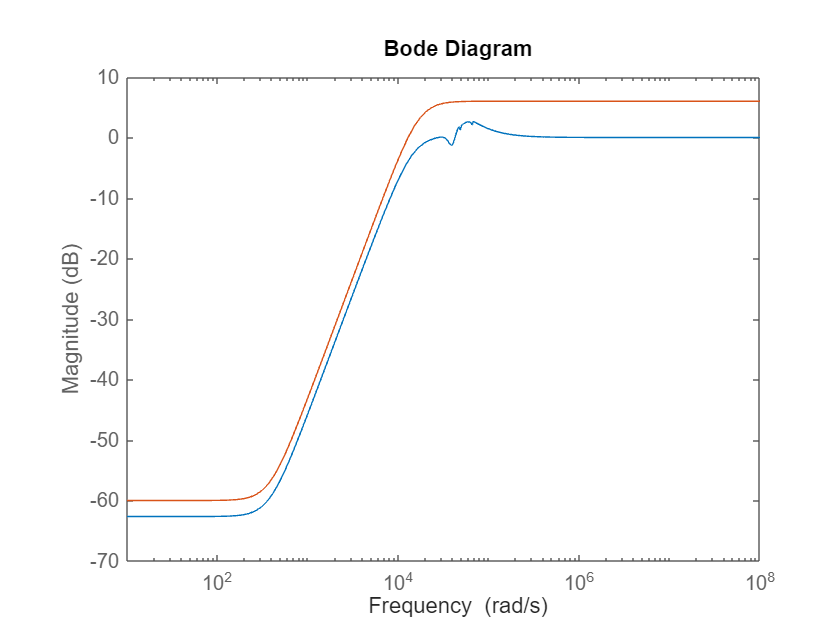

bodemag(inv(1+P*K), 1/Ws)

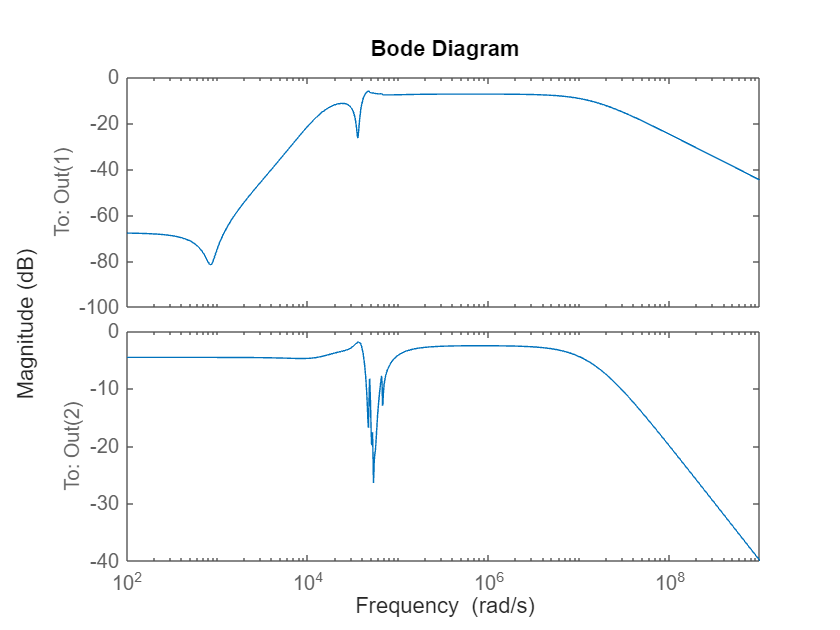

bodemag(Wu*K*inv(1+P*K))